# Balancing CONTROL LAW design:   mobile pivot pendulum.

In this case study we're going to design a CONTROL LAW that balances the mobile pendulum shown below.  The only energy dissipation experienced by this machine, occurs as viscous friction at the pivot point "o".  The approach that we'll follow includes the following:

- Derive the angular Equation of Motion (EoM) for the machine

- Do a "change" of variable for convenience

- Define a linear control law assuming full state feedback

- Perform pole placement to achieve a stable regulated system.

  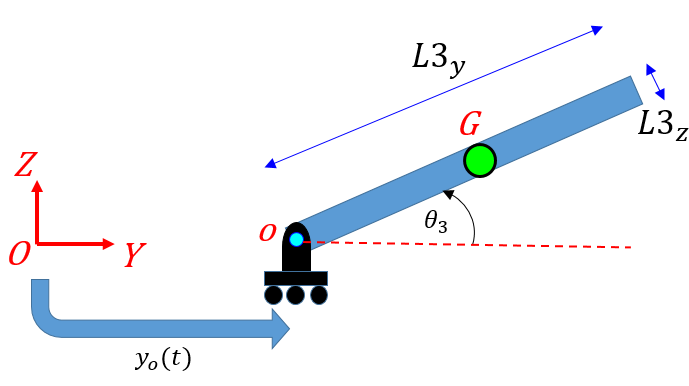         

**WHY are we doing this ?**

Our ultimate goal is to have an open chain robotic manipulator being capable of swinging up it's unactuated end link and balancing it. So in order to solve that larger problem, we'll initially focus on the simpler system that is the "mobile pivot" pendulum.

`Bradley ``Hort``on :`` 21-Apr-``2017, bradley.horton@mathworks.com.au` 

**Define some model parameters** 

Here are some model parameters:

syms    m3_s    % masses
syms    b3_s    % damping
syms     g_s    % gravity 
syms   I_G_s    % Inertia about CoM

syms L3X_s   L3Y_s   L3Z_s  % lengths for LINK #3

Position degrees of freedom:

syms t theta3(t)  yo(t)

Some convenience symbols:

syms theta_s  theta_D_s  theta_DD_s
syms    yo_s     yo_D_s     yo_DD_s

actual_LIST = [theta3(t), diff(theta3(t)),  diff(theta3(t),t,2), ...
                   yo(t), diff(    yo(t)),  diff(    yo(t),t,2)];
               
holder_LIST = [theta_s,  theta_D_s,  theta_DD_s, ...
                  yo_s,     yo_D_s,     yo_DD_s];

**Define Center of mass positions and TRANSLATIONAL velocities for ARM link:**

- 

**Consider LINK_3:** *What is the position vector for the center of mass "G" ? *

- 
$$y\left(t\right)=y_o \left(t\right)\text{  }+\text{ }\frac{L}{2}\ldotp \mathrm{cos}\left(\theta \right)$$


- 
$$z\left(t\right)=\frac{L}{2}\ldotp \mathrm{sin}\left(\theta \right)$$


G3      =         sym([0;0;0]);
G3(2,1) = yo(t) + (L3Y_s/2)*cos(theta3(t));  % y
G3(3,1) =         (L3Y_s/2)*sin(theta3(t));  % z

Now calculate our ***translational velocities*** and **accelerations** for the link:

WF_tran_vel_G3 = diff( G3, t); 
WF_tran_acc_G3 = diff( G3, t, 2); 

Here's what the translational velocity vector $\left\lbrack \begin{array}{c}
\dot{x} \\
\dot{y} \\
\dot{z} 
\end{array}\right\rbrack$ looks like for the center of mass of Link #3:

WF_tran_vel_G3

$$WF\_tran\_vel\_G3 = \left(\begin{array}{c} 0\\ \frac{\partial }{\partial t}\mathrm{yo}\left(t\right)-\frac{{\mathrm{L3Y}}_{s}\,\sin\left(\theta_{3}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{3}\left(t\right)}{2}\\ \frac{{\mathrm{L3Y}}_{s}\,\cos\left(\theta_{3}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{3}\left(t\right)}{2} \end{array}\right)$$

Here's what the translational acceleration vector $\left\lbrack \begin{array}{c}
\ddot{x} \\
\ddot{y} \\
\ddot{z} 
\end{array}\right\rbrack$ looks like for the center of mass of Link #3:

WF_tran_acc_G3

$$WF\_tran\_acc\_G3 = \left(\begin{array}{c} 0\\ \frac{\partial^{2}}{\partial t^{2}}\mathrm{yo}\left(t\right)-\frac{{\mathrm{L3Y}}_{s}\,\cos\left(\theta_{3}\left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\theta_{3}\left(t\right)\right)}^{2}}{2}-\frac{{\mathrm{L3Y}}_{s}\,\sin\left(\theta_{3}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\theta_{3}\left(t\right)}{2}\\ \frac{{\mathrm{L3Y}}_{s}\,\cos\left(\theta_{3}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\theta_{3}\left(t\right)}{2}-\frac{{\mathrm{L3Y}}_{s}\,\sin\left(\theta_{3}\left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\theta_{3}\left(t\right)\right)}^{2}}{2} \end{array}\right)$$

**Apply Newton's 2nd law:**

y_G_DD   = WF_tran_acc_G3(2);
z_G_DD   = WF_tran_acc_G3(3);
theta_DD = diff(theta3(t),t,2);

- 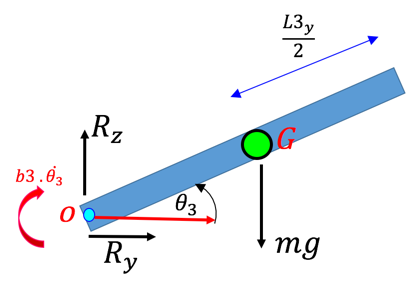

So Newton's equations are:

- 
$$m\ldotp \ddot{y_G } =\Sigma F_Y =R_Y$$


- 
$$m\ldotp \ddot{z_G } =\Sigma F_Z =R_Z -\mathrm{mg}$$


- 
$$I_G \ldotp \ddot{\theta_G } =\Sigma M_X =R_Y \ldotp \frac{L}{2}\ldotp \sin \left(\theta \right)-R_Z \ldotp \frac{L}{2}\ldotp \cos \left(\theta \right)-b_3 \ldotp \theta^{˙}$$


R_Y =  m3_s * y_G_DD;
R_Z = (m3_s * z_G_DD) + m3_s*g_s;

EQ  = I_G_s*theta_DD == R_Y*(L3Y_s/2)*sin(theta3(t)) - ...
                        R_Z*(L3Y_s/2)*cos(theta3(t)) - b3_s*diff(theta3(t));
EQ_theta_DD  = simplify(EQ)

$$EQ\_theta\_DD = m_{3,s}\,{{\mathrm{L3Y}}_{s}}^{2}\,\frac{\partial^{2}}{\partial t^{2}}\theta_{3}\left(t\right)+4\,I_{G,s}\,\frac{\partial^{2}}{\partial t^{2}}\theta_{3}\left(t\right)+4\,b_{3,s}\,\frac{\partial }{\partial t}\theta_{3}\left(t\right)+g_{s}\,m_{3,s}\,\cos\left(\theta_{3}\left(t\right)\right)\,{\mathrm{L3Y}}_{s}\,2=2\,{\mathrm{L3Y}}_{s}\,m_{3,s}\,\sin\left(\theta_{3}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\mathrm{yo}\left(t\right)$$

And isolate $\theta^{¨}$ :

new_EQ       = subs(EQ_theta_DD, diff(theta3,t,2), theta_DD_s);
THE_THETA_DD = solve(new_EQ, theta_DD_s);
expand(THE_THETA_DD)

$$ans = \frac{2\,{\mathrm{L3Y}}_{s}\,m_{3,s}\,\sin\left(\theta_{3}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\mathrm{yo}\left(t\right)}{m_{3,s}\,{{\mathrm{L3Y}}_{s}}^{2}+4\,I_{G,s}}-\frac{4\,b_{3,s}\,\frac{\partial }{\partial t}\theta_{3}\left(t\right)}{m_{3,s}\,{{\mathrm{L3Y}}_{s}}^{2}+4\,I_{G,s}}-\frac{2\,{\mathrm{L3Y}}_{s}\,g_{s}\,m_{3,s}\,\cos\left(\theta_{3}\left(t\right)\right)}{m_{3,s}\,{{\mathrm{L3Y}}_{s}}^{2}+4\,I_{G,s}}$$

So we can see that we have the following equation:

- 
$$\left.{\left(4\ldotp I\right.}_G +{\text{mL}}^2 \text{ }\right)\ldotp \theta^{¨} \text{ }\text{ }\text{ }\text{ }=\text{ }\text{ }2\text{ }\ldotp L\ldotp m\ldotp \sin \left(\theta \right)\ldotp \ddot{y_O } \text{  }-\text{ }\text{ }4\ldotp b_3 \ldotp \theta^{˙} \text{ }-\text{  }2\ldotp L\ldotp g\ldotp m\ldotp \cos \left(\theta \right)\text{ }$$
 

Which we can rearrange to (multipy both sides by $\frac{1}{4}$):

- 
$$\left(I_G +\frac{{\text{mL}}^2 }{4}\right)\text{ }\ldotp \theta^{¨} \text{ }\text{ }\text{ }\text{ }=\text{ }\text{ }\frac{L}{2}\ldotp m\ldotp \sin \left(\theta \right)\ldotp \ddot{y_O } \text{   }-{\text{  }b}_3 \ldotp \theta^{˙} \text{ }\text{ }\text{ }\text{ }-\text{ }\frac{L}{2}\ldotp g\ldotp m\ldotp \cos \left(\theta \right)\text{ }$$


And applying the Parallel Axis Theorem:  $I_{o\text{ }} =I_{G\text{  }} +{\mathrm{md}}^2 \text{ }=I_G \text{ }+\frac{{\text{mL}}^2 }{4}\text{ }$

- 
$$I_o \text{ }\ldotp \theta^{¨} \text{ }\text{ }\text{ }\text{ }=\text{ }\text{ }\frac{L}{2}\ldotp m\ldotp \sin \left(\theta \right)\ldotp \ddot{y_O } \text{   }-\text{ }{\text{ }b}_3 \ldotp \theta^{˙} \text{   }-\text{  }\frac{L}{2}\ldotp g\ldotp m\ldotp \cos \left(\theta \right)\mathit{ }$$


or isolating $\theta^{¨}$ we get :

- 
$$\theta^{¨} \text{ }\text{ }\text{ }\text{ }=\text{ }\text{ }\frac{L}{2\ldotp I_o }\ldotp m\ldotp \sin \left(\theta \right)\ldotp \ddot{y_O } \text{   }-\frac{b_3 }{I_o }\ldotp \theta^{˙} \text{   }-\text{  }\frac{L}{2\ldotp I_o }\ldotp g\ldotp m\ldotp \cos \left(\theta \right)\mathit{ }$$


## Balancing: let's change the angular description

- 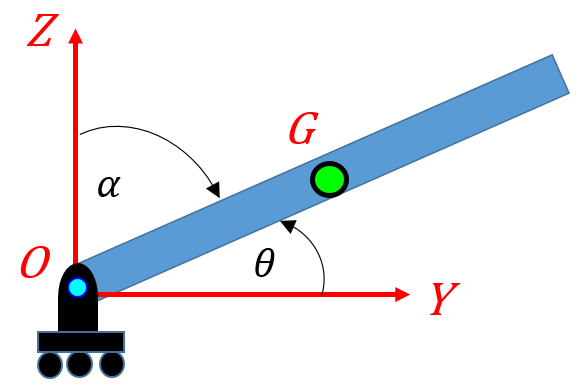 

Consider the following change of variable:

- $\alpha =\frac{\pi }{2}-\theta$   ,    $\alpha^{˙} =-\theta^{˙}$   ,   $\alpha^{¨} =-\theta^{¨}$

- 
$$\mathrm{sin}\left(\theta \right)=\mathrm{sin}\left(\frac{\pi }{2}-\alpha \right)=\mathrm{cos}\left(\alpha \right)$$


- 
$$\mathrm{cos}\left(\theta \right)=\mathrm{cos}\left(\frac{\pi }{2}-\alpha \right)=\mathrm{sin}\left(\alpha \right)$$
 

So our system equation of motion can be trans formed from:

- 
$$\theta^{¨} \text{ }\text{ }\text{ }\text{ }=\text{ }\text{ }\frac{L}{2\ldotp I_o }\ldotp m\ldotp \sin \left(\theta \right)\ldotp \ddot{y_O } \text{   }-\frac{b_3 }{I_o }\ldotp \theta^{˙} \text{   }-\text{  }\frac{L}{2\ldotp I_o }\ldotp g\ldotp m\ldotp \cos \left(\theta \right)$$


to this:

- 
$$-\alpha^{¨} \text{ }\text{ }\text{ }\text{ }=\text{ }\text{ }\frac{L}{2\ldotp I_o }\ldotp m\ldotp \mathrm{cos}\left(\alpha \right)\ldotp \ddot{y_O } \text{  }+\text{  }\frac{b_3 }{I_o }\ldotp \alpha^{˙} \text{   }-\text{  }\frac{L}{2\ldotp I_o }\ldotp g\ldotp m\ldotp \mathrm{sin}\left(\alpha \right)$$


So our new system equation is now:

- 
$$\alpha^{¨} \text{ }\text{ }\text{ }\text{ }=\text{ }\text{ }\frac{-\mathbf{L}}{2\ldotp {\mathbf{I}}_{\mathbf{o}} }\ldotp \mathbf{m}\ldotp \cos \left(\alpha \right)\ldotp \ddot{{\mathbf{y}}_{\mathbf{O}} } \text{  }+\text{  }\frac{-{\mathbf{b}}_3 }{{\mathbf{I}}_{\mathbf{o}} }\ldotp \alpha^{˙} \text{  }+\text{  }\frac{\mathbf{L}}{2\ldotp {\mathbf{I}}_{\mathbf{o}} }\ldotp \mathbf{g}\ldotp \mathbf{m}\ldotp \sin \left(\alpha \right)$$


syms alpha_s  alpha_D_s  alpha_DD_s  Io_s

THE_ALPHA_DD = subs(-1*THE_THETA_DD, actual_LIST, holder_LIST);
THE_ALPHA_DD = subs(THE_ALPHA_DD, {theta_s  theta_D_s  theta_DD_s}, ...
                                  {(pi/2 - alpha_s), -alpha_D_s, -alpha_DD_s} );
THE_ALPHA_DD = expand(THE_ALPHA_DD)

$$THE\_ALPHA\_DD = \frac{2\,{\mathrm{L3Y}}_{s}\,g_{s}\,m_{3,s}\,\sin\left(\alpha_{s}\right)}{m_{3,s}\,{{\mathrm{L3Y}}_{s}}^{2}+4\,I_{G,s}}-\frac{4\,\alpha_{D,s}\,b_{3,s}}{m_{3,s}\,{{\mathrm{L3Y}}_{s}}^{2}+4\,I_{G,s}}-\frac{2\,{\mathrm{L3Y}}_{s}\,m_{3,s}\,{\mathrm{yo}}_{\mathrm{DD},s}\,\cos\left(\alpha_{s}\right)}{m_{3,s}\,{{\mathrm{L3Y}}_{s}}^{2}+4\,I_{G,s}}$$

THE_ALPHA_DD = subs(THE_ALPHA_DD,{(m3_s*(L3Y_s)^2 + 4*I_G_s)}, {4*Io_s})

$$THE\_ALPHA\_DD = \frac{{\mathrm{L3Y}}_{s}\,g_{s}\,m_{3,s}\,\sin\left(\alpha_{s}\right)}{2\,{\mathrm{Io}}_{s}}-\frac{\alpha_{D,s}\,b_{3,s}}{{\mathrm{Io}}_{s}}-\frac{{\mathrm{L3Y}}_{s}\,m_{3,s}\,{\mathrm{yo}}_{\mathrm{DD},s}\,\cos\left(\alpha_{s}\right)}{2\,{\mathrm{Io}}_{s}}$$

## What does the system look look like near $\alpha =0$ ? 

Near the upright position we have:

- $\mathrm{sin}\left(\alpha \right)\approx \alpha$   ,   and  $\mathrm{cos}\left(\alpha \right)\approx 1$

THE_ALPHA_DD = subs(THE_ALPHA_DD, {sin(alpha_s), cos(alpha_s)}, {alpha_s, 1})

$$THE\_ALPHA\_DD = \frac{{\mathrm{L3Y}}_{s}\,\alpha_{s}\,g_{s}\,m_{3,s}}{2\,{\mathrm{Io}}_{s}}-\frac{{\mathrm{L3Y}}_{s}\,m_{3,s}\,{\mathrm{yo}}_{\mathrm{DD},s}}{2\,{\mathrm{Io}}_{s}}-\frac{\alpha_{D,s}\,b_{3,s}}{{\mathrm{Io}}_{s}}$$

So our new linear system is:

- 
$$\alpha^{¨} \text{ }\text{ }\text{ }\text{ }=\text{ }\text{ }\frac{-\mathbf{L}}{2\ldotp {\mathbf{I}}_{\mathbf{o}} }\ldotp \mathbf{m}\ldotp \ddot{{\mathbf{y}}_{\mathbf{O}} } \text{  }+\text{  }\frac{-{\mathbf{b}}_3 }{{\mathbf{I}}_{\mathbf{o}} }\ldotp \alpha^{˙} \text{  }+\text{  }\frac{\mathbf{L}}{2\ldotp {\mathbf{I}}_{\mathbf{o}} }\ldotp \mathbf{g}\ldotp \mathbf{m}\ldotp \alpha$$


Convert into a system of 1st order ODEs with the following state vector:

- $q=\left\lbrace \alpha ,\dot{\text{ }\alpha } \right\rbrace$  and  $\dot{q} =\left\lbrace \alpha^{˙} ,\ddot{\text{  }\alpha } \right\rbrace$

q_dot_col_s(1,1)     = formula( alpha_D_s  );
q_dot_col_s(2,1)     = formula(  THE_ALPHA_DD  )

$$q\_dot\_col\_s = \left(\begin{array}{c} \alpha_{D,s}\\ \frac{{\mathrm{L3Y}}_{s}\,\alpha_{s}\,g_{s}\,m_{3,s}}{2\,{\mathrm{Io}}_{s}}-\frac{{\mathrm{L3Y}}_{s}\,m_{3,s}\,{\mathrm{yo}}_{\mathrm{DD},s}}{2\,{\mathrm{Io}}_{s}}-\frac{\alpha_{D,s}\,b_{3,s}}{{\mathrm{Io}}_{s}} \end{array}\right)$$

And get this into a LINEAR matrix form:

[A,b] = equationsToMatrix(q_dot_col_s,{alpha_s, alpha_D_s})

$$A = \left(\begin{array}{cc} 0 & 1\\ \frac{{\mathrm{L3Y}}_{s}\,g_{s}\,m_{3,s}}{2\,{\mathrm{Io}}_{s}} & -\frac{b_{3,s}}{{\mathrm{Io}}_{s}} \end{array}\right)$$

$$b = \left(\begin{array}{c} 0\\ \frac{{\mathrm{L3Y}}_{s}\,m_{3,s}\,{\mathrm{yo}}_{\mathrm{DD},s}}{2\,{\mathrm{Io}}_{s}} \end{array}\right)$$

and now specify in STATE SPACE form:

- $\dot{q} =A\ldotp q\text{ }+B\ldotp u$,   where    $\ddot{y_O } =u$  

A_mat = A;
B_mat = -1*[0; coeffs(b(2),yo_DD_s)]

$$B\_mat = \left(\begin{array}{c} 0\\ -\frac{{\mathrm{L3Y}}_{s}\,m_{3,s}}{2\,{\mathrm{Io}}_{s}} \end{array}\right)$$

Let's look for a stabilizing control effort where:

- $\ddot{y_O } =u$    and $\text{  }u=-1\text{ }\ldotp \left\lbrack \begin{array}{c}
k_1  & k_2 \text{    }k_3 \text{    }k_4 
\end{array}\right\rbrack \ldotp \left\lbrack \begin{array}{c}
\alpha \\
\alpha^{˙} \\
y_o \\
\dot{y_o } 
\end{array}\right\rbrack$

syms k1 k2 k3 k4

so our state space equation now has the form:

- 
$$\left\lbrack \begin{array}{c}
\alpha^{˙} \\
\alpha^{¨} \\
\dot{y_o } \\
\ddot{y_o } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
0 & 1 & 0 & 0\\
\frac{L\ldotp g\ldotp m}{2\ldotp I_o } & \frac{-b}{I_o } & 0 & 0\\
0 & 0 & 0 & 1\\
\frac{-k_1 }{2} & \frac{-k_2 }{2} & \frac{-k_3 }{2} & \frac{-k_4 }{2}
\end{array}\right\rbrack \ldotp \left\lbrack \begin{array}{c}
\alpha \\
\alpha^{˙} \\
y_o \\
\dot{y_o } 
\end{array}\right\rbrack \text{ }+\left\lbrack \begin{array}{c}
0\\
\frac{-L\ldotp m}{2\ldotp I_o }\\
0\\
\frac{1}{2}
\end{array}\right\rbrack \ldotp \left\lbrack \begin{array}{c}
{-k}_1  & {-k}_2 \text{   }-k_3 \text{   }-k_4 
\end{array}\right\rbrack \ldotp \left\lbrack \begin{array}{c}
\alpha \\
\alpha^{˙} \\
y_o \\
\dot{y_o } 
\end{array}\right\rbrack$$


A1_new = [A_mat, zeros(2,2);
         0,0,0,1;
         (-k1/2),(-k2/2), (-k3/2), (-k4/2)];
A2_new = [B_mat;0;(1/2)] * [(-k1),(-k2), (-k3), (-k4)];
A_new = A1_new + A2_new

$$A\_new = \left(\begin{array}{cccc} 0 & 1 & 0 & 0\\ \frac{{\mathrm{L3Y}}_{s}\,g_{s}\,m_{3,s}}{2\,{\mathrm{Io}}_{s}}+\frac{{\mathrm{L3Y}}_{s}\,k_{1}\,m_{3,s}}{2\,{\mathrm{Io}}_{s}} & \frac{{\mathrm{L3Y}}_{s}\,k_{2}\,m_{3,s}}{2\,{\mathrm{Io}}_{s}}-\frac{b_{3,s}}{{\mathrm{Io}}_{s}} & \frac{{\mathrm{L3Y}}_{s}\,k_{3}\,m_{3,s}}{2\,{\mathrm{Io}}_{s}} & \frac{{\mathrm{L3Y}}_{s}\,k_{4}\,m_{3,s}}{2\,{\mathrm{Io}}_{s}}\\ 0 & 0 & 0 & 1\\ -k_{1} & -k_{2} & -k_{3} & -k_{4} \end{array}\right)$$

Substitute some numeric values before doing next step:

res_T = bh_get_numeric_vals();
A_new = subs(A_new, {m3_s, b3_s, g_s, L3Y_s, Io_s}, ...
                    {res_T.mass3, res_T.b3_damp, res_T.g, ...
                    res_T.L3y, res_T.Io3_xx})

$$A\_new = \left(\begin{array}{cccc} 0 & 1 & 0 & 0\\ \frac{600\,k_{1}}{101}+\frac{414048987053933175}{7107243161944064} & \frac{600\,k_{2}}{101}-\frac{384}{101} & \frac{600\,k_{3}}{101} & \frac{600\,k_{4}}{101}\\ 0 & 0 & 0 & 1\\ -k_{1} & -k_{2} & -k_{3} & -k_{4} \end{array}\right)$$

So let's setup an eigenvalue problem and grab the characteristic equation:

syms s

my_char_eqn = det(s*eye(4) - A_new)

$$my\_char\_eqn = \frac{384\,k_{3}\,s}{101}-\frac{414048987053933175\,k_{3}}{7107243161944064}-\frac{414048987053933175\,k_{4}\,s}{7107243161944064}-\frac{600\,k_{1}\,s^{2}}{101}-\frac{600\,k_{2}\,s^{3}}{101}+k_{3}\,s^{2}+\frac{384\,k_{4}\,s^{2}}{101}+k_{4}\,s^{3}-\frac{414048987053933175\,s^{2}}{7107243161944064}+\frac{384\,s^{3}}{101}+s^{4}$$

And collect the co-efficients of $s^n$:

[C,T] = coeffs(my_char_eqn,s,'All')

$$C = \left(\begin{array}{ccccc} 1 & k_{4}-\frac{600\,k_{2}}{101}+\frac{384}{101} & k_{3}-\frac{600\,k_{1}}{101}+\frac{384\,k_{4}}{101}-\frac{414048987053933175}{7107243161944064} & \frac{384\,k_{3}}{101}-\frac{414048987053933175\,k_{4}}{7107243161944064} & -\frac{414048987053933175\,k_{3}}{7107243161944064} \end{array}\right)$$

$$T = \left(\begin{array}{ccccc} s^{4} & s^{3} & s^{2} & s & 1 \end{array}\right)$$

 Now let's define our desired POLE locations: 

poles_desired    = [-10, -20, -30, -40]/5;

And hence our desired characteristic equation:

desired_char_eqn =  (s-poles_desired(1))* ...
                    (s-poles_desired(2))* ...
                    (s-poles_desired(3))* ...
                    (s-poles_desired(4));
                
[C_des,T_des]    = coeffs(desired_char_eqn,s,'All')

$$C\_des = \left(\begin{array}{ccccc} 1 & 20 & 140 & 400 & 384 \end{array}\right)$$

$$T\_des = \left(\begin{array}{ccccc} s^{4} & s^{3} & s^{2} & s & 1 \end{array}\right)$$

Now solve for our system gains $\left\lbrack \begin{array}{c}
k_1  & k_2 \text{    }k_3 \text{    }k_4 
\end{array}\right\rbrack$:

my_EQN = C_des(2:end).' == C(2:end).';
sol_T  = solve(my_EQN, [k1,k2,k3,k4]);

So what do the gains look  like?

my_gains = double([sol_T.k1, sol_T.k2, sol_T.k3, sol_T.k4].')

my_gains =   -39.1525
   -3.9549
   -6.5914
   -7.2963


So define the NEW closed loop dynamic system:

- 
$$\dot{q} =A_{\mathrm{NEW}} \text{ }\ldotp q\text{ }$$


A_new    = subs(  A_new, {k1,k2,k3,k4}, {sol_T.k1, sol_T.k2, sol_T.k3, sol_T.k4});
A_new    = double(A_new);
my_B_mat = zeros(4,1);
my_C_mat = [1,0,0,0;
            0,1,0,0;
            0,0,1,0;
            -1*my_gains']; 
my_D_mat = 0;        
ss_sys   = ss(A_new, my_B_mat, my_C_mat, my_D_mat);

So let's look at the system's response from an initial state:

- $q_0 =\left\lbrack \alpha \text{ },\alpha^{˙} ,{\text{ }\text{ }y}_o ,\dot{\text{  }y_o } \right\rbrack =\left\lbrack \frac{10\ldotp \pi }{180},\frac{150\ldotp \pi }{180},0,0\right\rbrack$, 

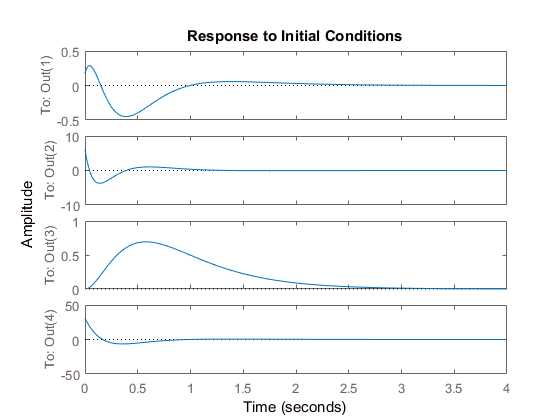

q0       = [10*pi/180;   350*pi/180;   0;   0];

initial(ss_sys,q0)      

**Simulink model implementation:**

The Simulink model <`bh_proto_balance_system.slx`> shows the implementation of this approach.  When you run the Simulink model, you get the following system response:    

-